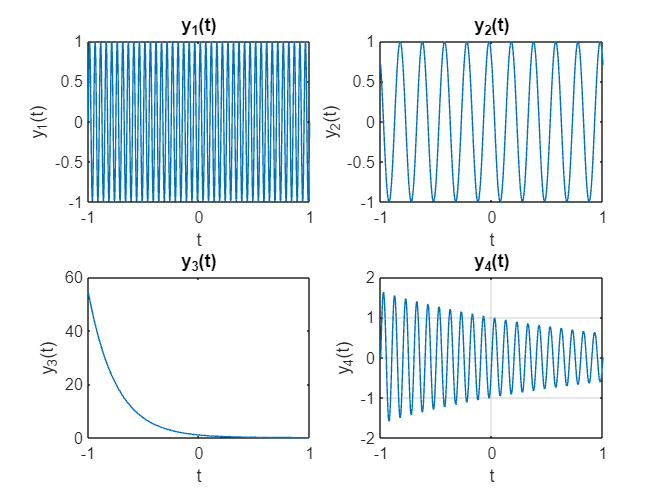

%question 1
t = linspace(-1, 1, 1000);
x = 235;
alpha = 1 + mod(x, 3);

y1 = sin(20 * pi * alpha * t);
y2 = cos(5 * pi * alpha * t + pi/4);
y3 = exp(-2 * alpha * t);
y4 = exp(-0.25 * alpha * t) .* sin(20 * pi * t);

figure;
subplot(2, 2, 1);
plot(t, y1);
xlabel('t');
ylabel('y_1(t)');
title('y_1(t)');

subplot(2, 2, 2);
plot(t, y2);
xlabel('t');
ylabel('y_2(t)');
title('y_2(t)');

subplot(2, 2, 3);
plot(t, y3);
xlabel('t');
ylabel('y_3(t)');
title('y_3(t)');

subplot(2, 2, 4);
plot(t, y4);
xlabel('t');
ylabel('y_4(t)');
title('y_4(t)');

grid on;

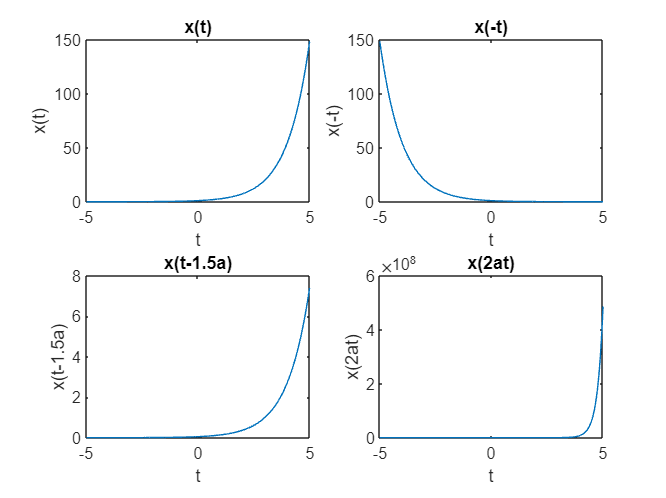

%Question 2
clear x;

t = linspace(-5, 5, 1000);
xt = x(t);
xt2 = x(-t);
xt3 = x(t - 1.5 * (1 + mod(235, 3)));
xt4 = x(2 * (1 + mod(235, 3)) * t);

figure;

subplot(2, 2, 1);
plot(t, xt);
xlabel('t');
ylabel('x(t)');
title('x(t)');


subplot(2, 2, 2);
plot(t, xt2);
xlabel('t');
ylabel('x(-t)');
title('x(-t)')

subplot(2, 2, 3);
plot(t, xt3);
xlabel('t');
ylabel('x(t-1.5a)');
title('x(t-1.5a)');

subplot(2, 2, 4);
plot(t, xt4);
xlabel('t');
ylabel('x(2at)');
title('x(2at)');

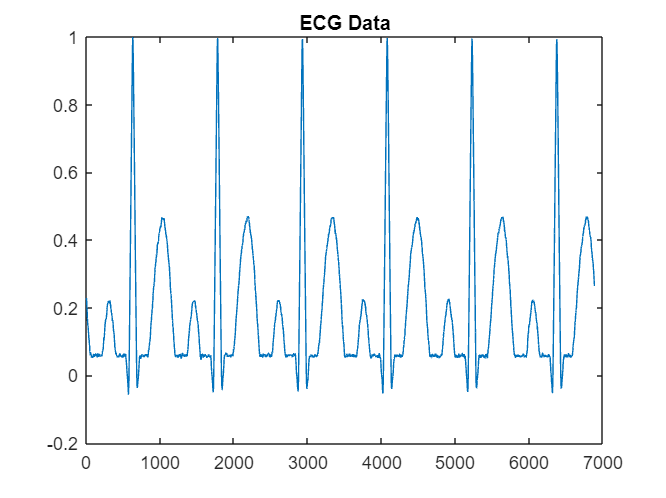

%Question 3
%1
ECG_data = load('ECG_Data.txt');

figure;
plot(ECG_data);
title('ECG Data');

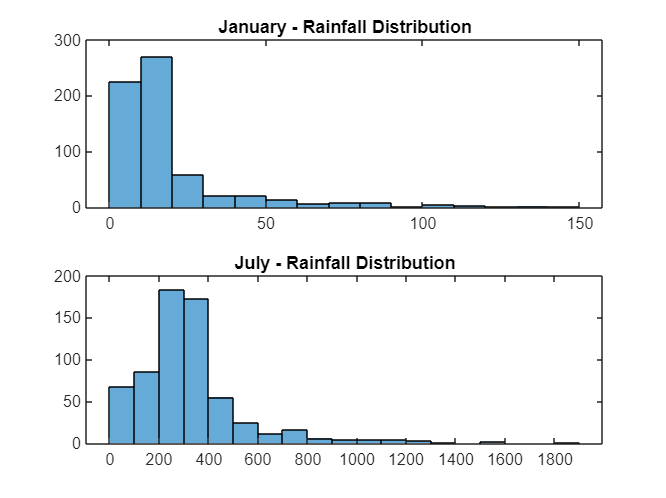

%x asis represents the actual data and y axis represetns the
%samples/indices


file_path = 'C:/Users/chand/OneDrive/Documents/EE/sem 5/Experiment-1/RainFallIndiaJan.txt'; 
addpath(fileparts(file_path));

%2
RainFall_Jan = load('RainFallIndia_Jan.txt');
RainFall_July = load('RainFallIndia_July.txt');

figure;
subplot(2, 1, 1);
histogram(RainFall_Jan);
title('January - Rainfall Distribution');

%x axis represents the range of rainfall values and y represents the
%frequency of occurance

subplot(2, 1, 2);
histogram(RainFall_July);
title('July - Rainfall Distribution');




mean_rainfall_Jan = mean(RainFall_Jan)

mean_rainfall_Jan = 18.3513

mean_rainfall_July = mean(RainFall_July)

mean_rainfall_July = 326.0936


std_rainfall_Jan = std(RainFall_Jan)

std_rainfall_Jan = 21.0991

std_rainfall_July = std(RainFall_July)

std_rainfall_July = 221.5326



[audio_data, sample_rate] = audioread('track002.wav');
sound(audio_data, sample_rate);

[speech_data, Fs] = audioread('speech.wav');

Error using audioread>readaudio
The filename specified was not found in the MATLAB path.

Error in audioread (line 160)
    [y, Fs] = readaudio (filename, range, datatype);


F = 250 * (1 + mod(235, 3));
modulated_signal = amplitude_modulation(speech_data, F, Fs);

t = (0:length(speech_data)-1) / Fs;
figure;
subplot(2, 1, 1);
plot(t, speech_data);
xlabel('Time (s)');
ylabel('Amplitude');
title('Original Speech Signal');
grid on;

subplot(2, 1, 2);
plot(t, modulated_signal);
xlabel('Time (s)');
ylabel('Amplitude');
title('Amplitude-Modulated Speech Signal');
grid on;

spectrum_speech = abs(fft(speech_data));
spectrum_modulated = abs(fft(modulated_signal));

figure;
subplot(2, 1, 1);
plot(spectrum_speech);
xlabel('Frequency (Hz)');
ylabel('Magnitude');
title('Spectrum of Original Speech Signal');
grid on;

subplot(2, 1, 2);
plot(spectrum_modulated);
xlabel('Frequency (Hz)');
ylabel('Magnitude');
title('Spectrum of Amplitude-Modulated Speech Signal');
grid on;

y(1)=sin(2*pi*(f(1)).*t);
y(2)=sin(2*pi*(f(2)).*t);
y(3)=sin(2*pi*(f(3)).*t);
y(4)=sin(2*pi*(f(4)).*t);
y(5)=sin(2*pi*(f(5)).*t);
y(6)=sin(2*pi*(f(6)).*t);
y(7)=sin(2*pi*(f(7)).*t);
y(8)=sin(2*pi*(f(8)).*t);


function y = amplitude_modulation(s, F, Fs)
    t = (0:length(s)-1) / Fs;
    y = s .* cos(2*pi*F*t);
end